Equação de transferencia de um filtro notch butterworth de segunda ordem: 

H(s) = K * (s² + ω₀²) / (s² + (ω₀/Q)s + ω₀²)

- ω0: frequência angular central da rejeição (em rad/s)

- Q: fator de qualidade do filtro

- K: ganho

- **Zeros**: São os valores de s (no domínio de Laplace) para os quais a função de transferência H(s) é **zero**. Ou seja, o filtro anula completamente o sinal nessas frequências (60Hz por exemplo).

- **Polos**: São os valores de s para os quais H(s) **tende ao infinito**. Eles indicam os pontos onde o sistema tem ganho máximo ou ressonância.

clc;
clear;

s = tf('s');
rad_s = 2 * pi;

f_center = 60; % Hz --> afeta a posição dos zeros
bw = 1;        % largura de banda em Hz
K = 1;        % Ganho

omega_0 = f_center * rad_s

omega_0 = 376.9911


Q = omega_0 / (bw*rad_s) % --> afeta a posição dos polos

Q = 60.0000



H = K * (s^2 + omega_0^2) / (s^2 + (omega_0/Q)*s + omega_0^2)


H =
 
       s^2 + 1.421e05
  ------------------------
  s^2 + 6.283 s + 1.421e05
 
Continuous-time transfer function.
Model Properties


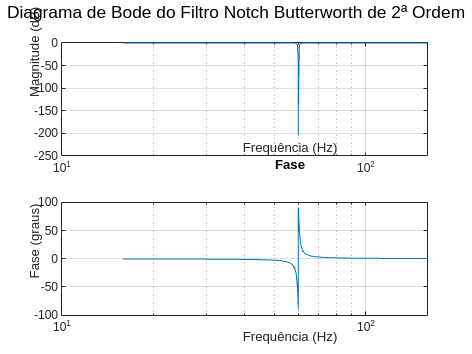


% Diagrama de Bode em Hz
[mag, phase, w] = bode(H); % w está em rad/s
mag = squeeze(mag);
phase = squeeze(phase);
f = w / rad_s; % conversão para Hz

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag));
grid on;
title('Magnitude');
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
subplot(2,1,2);
semilogx(f, phase);
grid on;
title('Fase');
xlabel('Frequência (Hz)');
ylabel('Fase (graus)');
sgtitle('Diagrama de Bode do Filtro Notch Butterworth de 2ª Ordem');

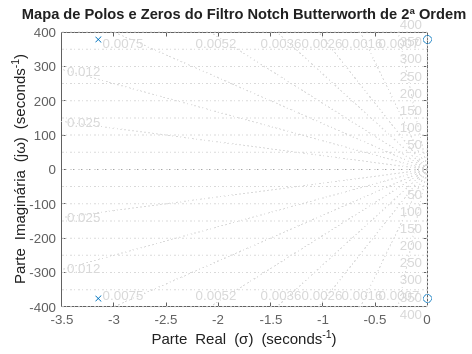


% Mapa de Polos e Zeros com labels ajustados
figure;
pzmap(H);
grid on;
title('Mapa de Polos e Zeros do Filtro Notch Butterworth de 2ª Ordem');
xlabel('Parte Real (σ)');
ylabel('Parte Imaginária (jω)');


disp('Polos:');

Polos:


disp(pole(H));

   1.0e+02 *

  -0.0314 + 3.7698i
  -0.0314 - 3.7698i



disp('Zeros:');

Zeros:


disp(zero(H));

   1.0e+02 *

   0.0000 + 3.7699i
   0.0000 - 3.7699i



Projeto analogico 

- feito com https://webench.ti.com/filter-design-tool

- Gain = 1V/V

- Center Freq = 60Hz

- Bandwidth = 1Hz

- Ripple = 1dB

- Order = 2

https://electroagenda.com/en/bainter-notch-filter-design-and-tuning/

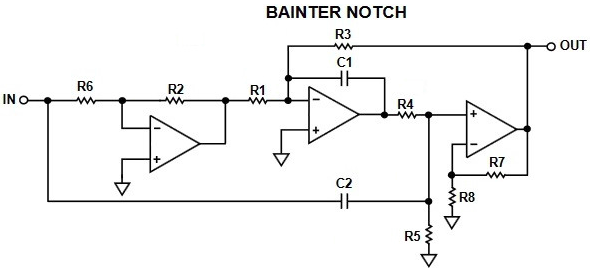

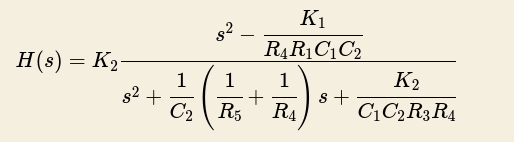

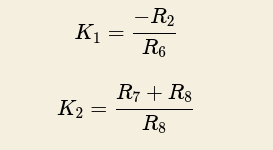

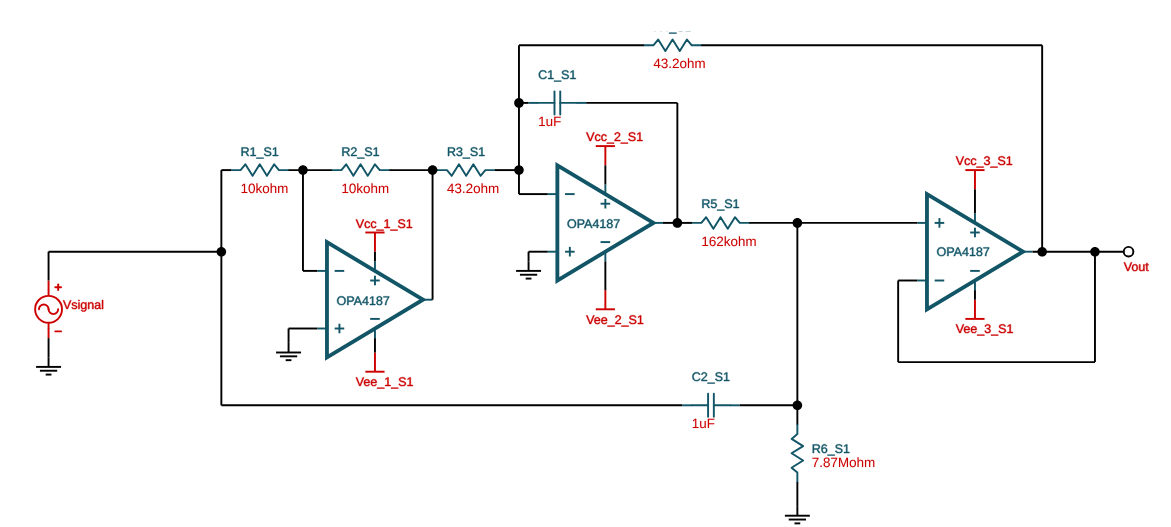

%Esses amp op escolhidos pelo designer são caros demais 
%preciso checar algo que atenda os requisitos do projeto
%sem ser tão caro
R1 = 43.2

R1 = 43.2000

R2 = 10e3 %k ohm

R2 = 10000

R3 = 43.2

R3 = 43.2000

R4 = 162e3 %k ohm

R4 = 162000

R5 = 7.87e6 %M ohm

R5 = 7870000

R6 = 10e3 %k ohm

R6 = 10000

R7 = 0

R7 = 0

R8 = 0

R8 = 0

C1 = 1e-6 %uF

C1 = 1.0000e-06

C2 = 1e-6 %uF

C2 = 1.0000e-06


K1 = -R2/R6

K1 = -1

K2 = 1 % amp op na configuração de buffer => ganho 1

K2 = 1


s = tf("s");

denominador = s^2 - (K1/(R4*R1*C1*C2))


denominador =
 
  s^2 + 1.429e05
 
Continuous-time transfer function.
Model Properties


divisor = s^2 + (1/C2)*((1/R5) + (1/R4))*s + K2/(C1*C2*R3*R4)


divisor =
 
  s^2 + 6.3 s + 1.429e05
 
Continuous-time transfer function.
Model Properties



H_ti = K2*(denominador/divisor)


H_ti =
 
      s^2 + 1.429e05
  ----------------------
  s^2 + 6.3 s + 1.429e05
 
Continuous-time transfer function.
Model Properties


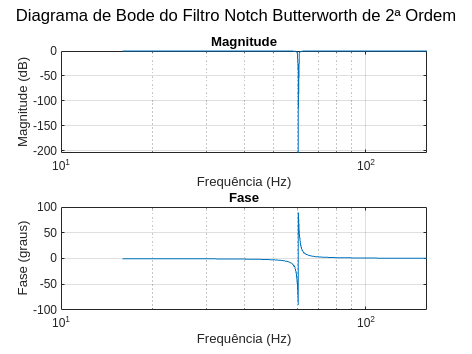


% Diagrama de Bode em Hz
[mag, phase, w] = bode(H_ti); % w está em rad/s
mag = squeeze(mag);
phase = squeeze(phase);
f = w / rad_s; % conversão para Hz

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag));
grid on;
title('Magnitude');
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
subplot(2,1,2);
semilogx(f, phase);
grid on;
title('Fase');
xlabel('Frequência (Hz)');
ylabel('Fase (graus)');
sgtitle('Diagrama de Bode do Filtro Notch Butterworth de 2ª Ordem');

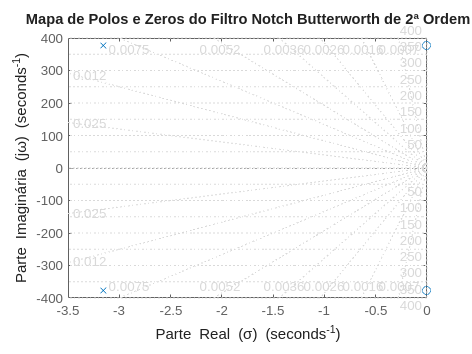


% Mapa de Polos e Zeros com labels ajustados
figure;
pzmap(H_ti);
grid on;
title('Mapa de Polos e Zeros do Filtro Notch Butterworth de 2ª Ordem');
xlabel('Parte Real (σ)');
ylabel('Parte Imaginária (jω)');


disp('----- Eq transf original -----')

----- Eq transf original -----


disp('Polos:');

Polos:


disp(pole(H));

   1.0e+02 *

  -0.0314 + 3.7698i
  -0.0314 - 3.7698i



disp('Zeros:');

Zeros:


disp(zero(H));

   1.0e+02 *

   0.0000 + 3.7699i
   0.0000 - 3.7699i



disp('--------- TI designer --------')

--------- TI designer --------


disp('Polos:');

Polos:


disp(pole(H_ti));

   1.0e+02 *

  -0.0315 + 3.7799i
  -0.0315 - 3.7799i



disp('Zeros:');

Zeros:


disp(zero(H_ti));

   1.0e+02 *

   0.0000 + 3.7801i
   0.0000 - 3.7801i

